TrendTrading Optimization

Single variable

clear 

tic

options = optimoptions ('ga', 'UseParallel', true, 'UseVectorized', false)
options = optimoptions(options,'PlotFcn',{@gaplotbestf,@gaplotstopping});
options.MaxGenerations = 50 ;
FitnessFunction = @(x) TrendTradingFcn (x);
nvars = 1 ;
lb = [0]
ub = [0.5]
[x, fval] = ga(FitnessFunction, nvars, [], [], [], [], lb, ub, [], [], options)


toc



Double variable

clear 

tic

rng (1, 'twister') % for reproducibility
options = optimoptions ('ga', 'UseParallel', true, 'UseVectorized', false)
options = optimoptions(options,'PlotFcn',{@gaplotbestf,@gaplotstopping});
options.MaxGenerations = 50 ;
FitnessFunction = @(x) TrendTradingFcnDoubleVar (x);
nvars = 2 ;
lb = [1, 0]
ub = [80, 0.5]
IntCon = 1 ;
[x, fval] = ga(FitnessFunction, nvars, [], [], [], [], lb, ub, [], IntCon, options)


toc

Multivariable

clear 

tic

options = optimoptions ('ga', 'UseParallel', true, 'UseVectorized', false)

options =   ga options:

   Set properties:
                     UseParallel: 1
                   UseVectorized: 0

   Default properties:
             ConstraintTolerance: 1.0000e-03
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
               CrossoverFraction: 0.8000
                         Display: 'final'
                      EliteCount: '0.05*PopulationSize'
                    FitnessLimit: -Inf
               FitnessScalingFcn: @fitscalingrank
               FunctionTolerance: 1.0000e-06
                       HybridFcn: []
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
                  MaxGenerations: '100*numberOfVariables'
             MaxStallGenerations: 50
                    MaxStallTime: Inf
                         MaxTime: Inf
                     M

options = optimoptions(options,'PlotFcn',{@gaplotbestf,@gaplotstopping})

options =   ga options:

   Set properties:
                         PlotFcn: {@gaplotbestf  @gaplotstopping}
                     UseParallel: 1
                   UseVectorized: 0

   Default properties:
             ConstraintTolerance: 1.0000e-03
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
               CrossoverFraction: 0.8000
                         Display: 'final'
                      EliteCount: '0.05*PopulationSize'
                    FitnessLimit: -Inf
               FitnessScalingFcn: @fitscalingrank
               FunctionTolerance: 1.0000e-06
                       HybridFcn: []
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
                  MaxGenerations: '100*numberOfVariables'
             MaxStallGenerations: 50
                    MaxStallTime

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).

ans =

   -0.0163


ans =

   -0.0011


ans =

   -0.0011


ans =

   -0.0308


ans =

   7.6453e-04


EndCumSum =

    0.9735


ans =

   7.6453e-04


EndCumSum =

    0.9987


ans =

    0.0039


EndCumSum =

    1.0031


ans =

    0.0463


EndCumSum =

    0.8358


TradingPeriod =

    9.0055


CAGR =

   -0.0030


SharpeRatio =

    0.4708


Sortino =

    0.4706


MomMainRetThreshold =

    76

Elapsed time is 16.047558 seconds.

TradingPeriod =

    9.0055


CAGR =

  -1.4926e-04


SharpeRatio =

    0.2751


Sortino =

    0.2787


MomMainRetThreshold =

    70

Elapsed time is 16.283945 seconds.

TradingPeriod =

    9.0055


CAGR =

   3.4413e-04


SharpeRatio =

   -0.2649


Sortino =

   -0.6447


MomMainRetThreshold =

    48

Elapsed time is 16.038736 seconds.

TradingPeriod =

    9.0055


CAGR =

   -0.0197


SharpeRatio =

    0.3587


Sortino =

    0


ans =

     0


ans =

     0


ans =

     0


ans =

   -0.0011


ans =

   7.6453e-04


EndCumSum =

    1.0003


TradingPeriod =

    9.0055


CAGR =

   2.9370e-05


SharpeRatio =

   -0.3337


Sortino =

  -Inf


MomMainRetThreshold =

    88

Elapsed time is 3.224744 seconds.

ans =

   7.6453e-04


EndCumSum =

    1.0003


TradingPeriod =

    9.0055


CAGR =

   2.9370e-05


SharpeRatio =

   -0.3337


Sortino =

  -Inf


MomMainRetThreshold =

    62

Elapsed time is 3.211082 seconds.

ans =

   7.6453e-04


EndCumSum =

    1.0003


TradingPeriod =

    9.0055


CAGR =

   2.9370e-05


SharpeRatio =

   -0.3337


Sortino =

  -Inf


MomMainRetThreshold =

    33

Elapsed time is 3.123741 seconds.

ans =

    0.0213


EndCumSum =

    1.0240


TradingPeriod =

    9.0055


CAGR =

    0.0026


SharpeRatio =

   -0.3598


Sortino =

   -4.9656


MomMainRetThreshold =

    32

Elapsed time is 3.217924 seconds.

ans =

     0


ans =

     0


ans =

   -0.0011


ans =

   -0.

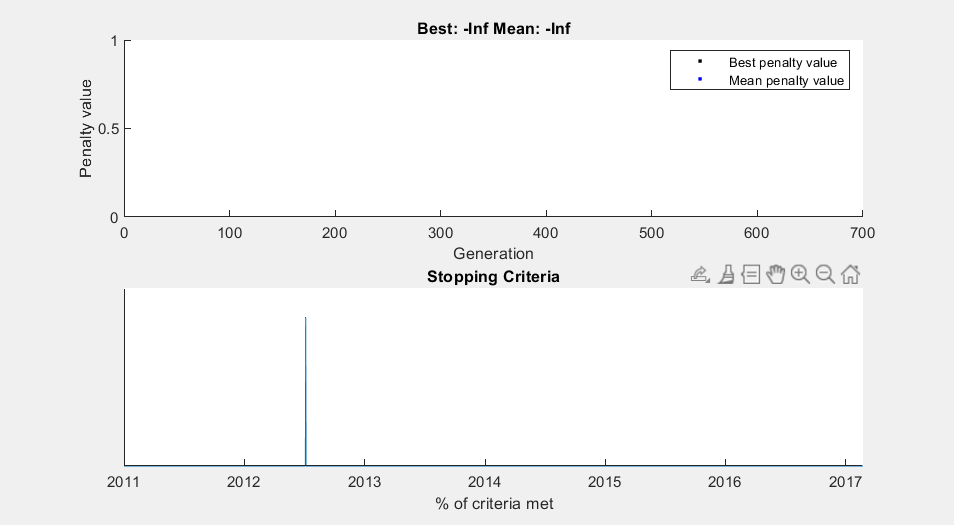

ans = 0

ans = 7.6453e-04

EndCumSum = 1.0003

TradingPeriod = 9.0055

CAGR = 2.9370e-05

SharpeRatio = -0.3337

Sortino = -Inf

MomMainRetThreshold = 88

Elapsed time is 3.666538 seconds.
Optimization terminated: minimum penalty fitness limit reached
and constraint violation is less than options.ConstraintTolerance.


x = 	1.0e+11 *

    4.2176    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


fval = -Inf

% options.MaxGenerations = 50 ;
options.FunctionTolerance = 1.0e-2 ;
FitnessFunction = @(x) TrendTradingFcnMultiVar(x) ;
nvars = 7 ;
IntCon = [1, 2, 3, 4, 5, 6, 7 ] ;
lb = [100, 2, -30, 2, -10, 2, -20 ] ;
ub = [10^12, 60, 90, 90, 90, 10, 50 ] ;
[x, fval] = ga(FitnessFunction, nvars, [], [], [], [], lb, ub, [], IntCon, options)



toc

Elapsed time is 5.026889 seconds.
